clear all; close all; clc;

% ====================== 1. Parameter setting ======================
sf = 1000;                                  % Sampling frequency
ch_n = 62;                                  % Number of channels
wnd_size=[-0.2 1];                          % Window size
bpf = [0.5 30];                             % Frequency of band-pass
flash = 12;                                 % Flash number
seq = 5;                                    % Sequence number
fullscreen=get(0,'ScreenSize');             % Size of the monitor screen
[position]=EEG_62ch_layout_Brain_Products;  % EEG channel positions

% ====================== 2. Data load ======================
load('D:\W00Y0NG\PRGM2\MATLAB\PhDYeom\data\sess01_subj24_EEG_ERP.mat');
EEG = EEG_ERP_train.x';            % For short name

% ====================== 3. Rereferencing (CAR)======================
EEG = EEG-repmat(mean(EEG,1), ch_n,1);

% ====================== 4. Band-pass filtering ===================
for ch=1:size(EEG,1)
    fil_EEG(ch, :)=bandpass(EEG(ch,:), bpf, sf); % Band-pass filtering
end

% ====================== 5. Extract events ======================
events{1}=EEG_ERP_train.t(find(EEG_ERP_train.y_dec==1)); % Target
events{2}=EEG_ERP_train.t(find(EEG_ERP_train.y_dec==2)); % Non-target

% ====================== 6. Epoching data ===================
for i=1:length(events)       
    for tr=1:size(events{i},2) 
        e_EEG{i}(:,:,tr) = fil_EEG(:,round(events{i}(tr)+(wnd_size(1)*sf)):round(events{i}(tr)+(wnd_size(2)*sf)));
    end
end

% ====================== 7. Averaging by trails ===================
for i=1:length(events)         % Class number
    m_EEG{i} = mean(e_EEG{i},3); % Averaging by trails
end

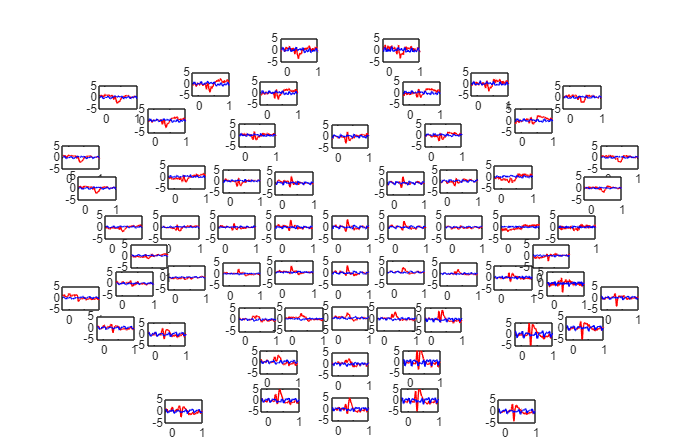

% ====================== 8. Plotting the EEG signals ===================
t=wnd_size(1):1/sf:wnd_size(2);
figure('Position',[0 0 fullscreen(3) fullscreen(4)]);
set(gcf,'color','w');

for ch=1:size(m_EEG{i},1)
    subplot('Position', position(ch,:));
    plot(t,m_EEG{1}(ch,:),'r',t,m_EEG{2}(ch,:),'b');
    xlim(wnd_size); ylim([-5 5]);
end

## =================== Training ===================

% ====================== 5. Parameter setting ======================
F_time=[0.2 0.5]; 
dur=[ceil((F_time(1)-wnd_size(1))*sf) : ceil((F_time(2)-wnd_size(1))*sf)];

char_seq= {'A', 'B', 'C', 'D', 'E', 'F', ...
    'G', 'H', 'I', 'J', 'K', 'L', ...
    'M', 'N', 'O', 'P', 'Q', 'R', ...
    'S', 'T', 'U', 'V', 'W', 'X', ...
    'Y', 'Z', '1', '2', '3', '4', ...
    '5', '6', '7', '8', '9', '_'};

load('random_cell_order.mat'); 
word='NEURAL_NETWORKS_AND_DEEP_LEARNING'; 

% ====================== 6. Extract events ======================
clear events
events=EEG_ERP_train.t;

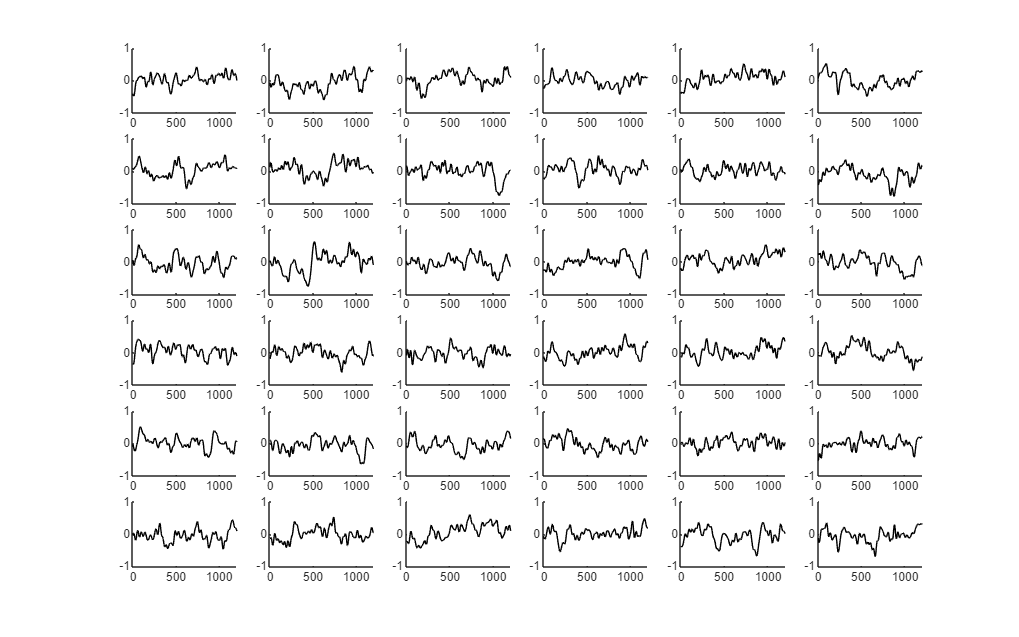

% ====================== 7. Epoching data ===================
for char=1:length(word)
    for sq=1:seq    
        temp=[]; temp1=[]; temp2=[];
        for tr=1:flash  
            eve=events(((char-1)*(seq*flash))+((sq-1)*flash)+tr);
          
            e_EEG=fil_EEG(:,round(eve+(wnd_size(1)*sf)):round(eve+(wnd_size(2)*sf)));
            
            temp(:,:,rc_order{sq}(tr,:),tr)=repmat(e_EEG,[1,1,6]);
        end
        rc_EEG(:,:,:,sq)=mean(temp,4);
    end
    rc_m_EEG{char}=mean(rc_EEG,4);
end
 

ch=14; char=1;
figure('Position',[0 0 fullscreen(3) fullscreen(4)]); 
for rc=1:length(char_seq)
    subplot(6,6,rc);hold on;
    plot(rc_m_EEG{char}(ch,:,rc),'k'); ylim([-1 1]);
end

% ====================== 8. Feature extraction ===================
for char=1:length(word) 
    for ch=1:size(rc_m_EEG{char},1)
        for tr=1:size(rc_m_EEG{char},3)
            [temp_ts, temp_idx]=findpeaks(rc_m_EEG{char}(ch, dur, tr),'SortStr','descend');
            peak_idx{char}(ch,tr)=temp_idx(1)+dur(1);
            peak{char}(ch,tr)=temp_ts(1);
        end
    end
end


ch=14;
for char=1:length(word) 
    figure('Position',[0 0 fullscreen(3) fullscreen(4)]);
    [M, I]= max(peak{char}(ch,:));
    for tr=1:size(rc_m_EEG{char},3)
        subplot(6,6,tr);hold on;
        plot(rc_m_EEG{char}(ch,:,tr),'k'); ylim([-1 1]);
        plot(peak_idx{char}(ch,tr),rc_m_EEG{char}(ch,peak_idx{char}(ch,tr),tr),'r*');
        if tr==I
            title('Predicted Target');
        end
    end
    fname = ['ERP_rc_char_',num2str(char), '.png']; saveas(gcf, fname, 'png');
    close all
end

% ====================== 9. Prediction ===================
for char=1:length(word)  
    [M, pred(char)]= max(peak{char}(ch,:));
    prediction(char)= char_seq{pred(char)};
    acc(char)=strcmp(word(char), prediction(char));
end

accuracy=mean(acc)

accuracy = 0.8611